clear;
clc;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J2 = 1.082635854e-3;
R = 6378.137e3;
a = 7211.54e3;
e = 0.01;
n = sqrt(mu / a^3);
INC     = deg2rad(98.7);
omega   = deg2rad(30);
theta_0 = deg2rad(45);

% Condiciones iniciales
x0  = 0;
y0  = 0;
z0  = 0;
dx0 = 0;
dy0 = 0;
dz0 = 0;

% Constantes de la memoria
eta     = n*t/2;
alpha1  =     omega +   theta_0;
alpha2  =   2*omega +   theta_0;
alpha3  =   2*omega + 3*theta_0;
alpha4  =     omega + 2*theta_0;
alpha5  =     omega + 3*theta_0;
alpha6  =     omega -   theta_0;


beta1   =       eta +    alpha1;
beta2   =     3*eta +  2*alpha1;
beta3   =       eta +  2*alpha1;
beta4   =       eta -  2*alpha1;
beta5   =     2*eta +    alpha1;
beta6   =     3*eta +    alpha1;
beta7   =     4*eta +    alpha1;
beta8   =    -  eta +    alpha1;
beta9   =   - 2*eta +    alpha1;

beta10  =     2*eta +    alpha2;
beta11  =     4*eta +    alpha2;
beta12  =   - 2*eta +    alpha2;

beta13  =    4*eta +    alpha3;
beta14  =    6*eta +    alpha3;
beta15  =  - 2*eta +    alpha3;

beta16  =      eta +    alpha4;
beta17  =    2*eta +    alpha4;
beta18  =    3*eta +    alpha4;
beta19  =    4*eta +    alpha4;
beta20  =    - eta +    alpha4;
beta21  =  - 2*eta +    alpha4;

beta22  =     2*eta +    alpha5;
beta23  =     4*eta +    alpha5;
beta24  =     6*eta +    alpha5;
beta25  =   - 2*eta +    alpha5;

beta26  =     2*eta +    alpha6;
beta27  =   - 2*eta +    alpha6;


tau1    =     2*eta +   theta_0;
tau2    =   - 2*eta +   theta_0;
o1      =       eta +     omega;
o2      =     2*eta +     omega;
o3      =     - eta +     omega;
o4      =   - 2*eta +     omega;
kappa_i = 3*cos(2*INC) + 1;

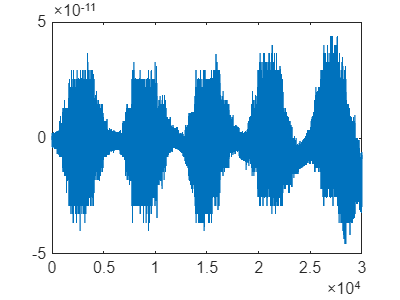

% Solución analítica
xJ2B    = ((640.*a.*n - 480.*a.*n.*cos(n.*t) - 2560.*a.*e.^2.*n + 3840.*a.*e.^4.*n - 2560.*a.*e.^6.*n + 640.*a.*e.^8.*n + 1920.*a.*e.^2.*n.*cos(n.*t) - 2880.*a.*e.^4.*n.*cos(n.*t) + 1920.*a.*e.^6.*n.*cos(n.*t) - 480.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*x0 + ((160.*sin(n.*t).*a - 640.*sin(n.*t).*a.*e.^2 + 960.*sin(n.*t).*a.*e.^4 - 640.*sin(n.*t).*a.*e.^6 + 160.*sin(n.*t).*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*160)).*dx0 + ((320.*a - 320.*a.*cos(n.*t) - 1280.*a.*e.^2 + 1920.*a.*e.^4 - 1280.*a.*e.^6 + 320.*a.*e.^8 + 1280.*a.*e.^2.*cos(n.*t) - 1920.*a.*e.^4.*cos(n.*t) + 1280.*a.*e.^6.*cos(n.*t) - 320.*a.*e.^8.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*dy0 + (-(60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(a.*n.*(- 1 + e.^2).^4.*160)).*t.*J2 + (-(60.*R.^2.*n - 60.*R.^2.*n.*cos(n.*t) - 30.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*cos(2.*INC + n.*t) - 90.*R.^2.*n.*cos(2.*INC - n.*t) + 180.*R.^2.*n.*cos(2.*INC) - 60.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 60.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 15.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 10.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 10.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 120.*R.^2.*n.*cos(2.*omega + 2.*theta_0) + 90.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 40.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 35.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 25.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 80.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 320.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 40.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) + 60.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 60.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 90.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) + 240.*R.^2.*e.^2.*n.*cos(2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) - 120.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 70.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) + 40.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 2.*n.*t) - 50.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 120.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0) - 120.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0) - 240.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 21.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 25.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 25.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 640.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 80.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 330.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 70.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 240.*R.^2.*e.*n.*cos(2.*omega + theta_0) + 480.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 50.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 50.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 4.*n.*t) - 40.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 40.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0))./(a.*n.*(- 1 + e.^2).^4.*160)).*J2;
yJ2B    = (-(960.*a.*n.^2 - 3840.*a.*e.^2.*n.^2 + 5760.*a.*e.^4.*n.^2 - 3840.*a.*e.^6.*n.^2 + 960.*a.*e.^8.*n.^2)./(a.*n.*(- 1 + e.^2).^4.*160)).*x0.*t + ((960.*a.*n.*sin(n.*t) - 3840.*a.*e.^2.*n.*sin(n.*t) + 5760.*a.*e.^4.*n.*sin(n.*t) - 3840.*a.*e.^6.*n.*sin(n.*t) + 960.*a.*e.^8.*n.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*x0 + ((160.*a.*n - 640.*a.*e.^2.*n + 960.*a.*e.^4.*n - 640.*a.*e.^6.*n + 160.*a.*e.^8.*n)./(a.*n.*(- 1 + e.^2).^4.*160)).*y0 + (-(640.*sin((n.*t)./2).^2.*a - 2560.*sin((n.*t)./2).^2.*a.*e.^2 + 3840.*sin((n.*t)./2).^2.*a.*e.^4 - 2560.*sin((n.*t)./2).^2.*a.*e.^6 + 640.*sin((n.*t)./2).^2.*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*160)).*dx0 + (-(480.*a.*n - 1920.*a.*e.^2.*n + 2880.*a.*e.^4.*n - 1920.*a.*e.^6.*n + 480.*a.*e.^8.*n)./(a.*n.*(- 1 + e.^2).^4.*160)).*dy0.*t + ((640.*sin(n.*t).*a - 2560.*sin(n.*t).*a.*e.^2 + 3840.*sin(n.*t).*a.*e.^4 - 2560.*sin(n.*t).*a.*e.^6 + 640.*sin(n.*t).*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*160)).*dy0 + (-(720.*R.^2.*e.^2.*n.^3.*sin(2.*omega) + 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC - 2.*omega) - 360.*R.^2.*e.^2.*n.^3.*sin(2.*INC + 2.*omega))./(a.*n.*(- 1 + e.^2).^4.*160)).*t.^2.*J2 + ((480.*R.^2.*n.^2 + 180.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 720.*R.^2.*e.*n.^2 + 180.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 360.*R.^2.*n.^2.*sin(omega + theta_0).^2 - 720.*R.^2.*n.^2.*sin(INC).^2 + 360.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(- INC + theta_0./2 + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 360.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2).^2 + 120.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 - 960.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 - 120.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 480.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 - 720.*R.^2.*e.*n.^2.*sin(omega + theta_0./2).^2 - 240.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 + 1920.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 - 240.*R.^2.*e.*n.^2.*cos(theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 240.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 + 720.*R.^2.*e.*n.^2.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 480.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2)./(a.*n.*(- 1 + e.^2).^4.*160)).*t.*J2 + ((140.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 60.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 120.*R.^2.*n.*sin(n.*t) + 10.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 180.*R.^2.*n.*sin(2.*INC + n.*t) + 180.*R.^2.*n.*sin(2.*INC - n.*t) + 45.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 45.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 30.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 30.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 70.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 5.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 5.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.*sin(2.*omega + 2.*theta_0) + 70.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) + 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 540.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 540.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 1080.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) - 840.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) + 720.*R.^2.*e.*n.*sin(2.*INC - theta_0) - 120.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) + 280.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) + 140.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 70.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 70.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) + 160.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) - 25.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 360.*R.^2.*e.*n.*sin(theta_0 + n.*t) + 120.*R.^2.*e.*n.*sin(theta_0 - n.*t) - 180.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 1920.*R.^2.*e.^2.*n.*sin(2.*omega) + 960.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 960.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 140.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) + 20.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 90.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) + 90.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) - 360.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 210.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) + 10.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 7.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) - 320.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) + 50.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) - 480.*R.^2.*e.*n.*sin(theta_0) + 540.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 540.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) + 420.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) - 720.*R.^2.*e.*n.*sin(2.*INC + theta_0) + 60.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 60.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 140.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) - 10.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 10.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) - 180.*R.^2.*e.*n.*sin(2.*omega + theta_0) + 720.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 420.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) + 40.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) + 20.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 84.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) - 20.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*J2;
zJ2B    = ((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*8)).*z0 + ((8.*sin(n.*t).*a - 32.*sin(n.*t).*a.*e.^2 + 48.*sin(n.*t).*a.*e.^4 - 32.*sin(n.*t).*a.*e.^6 + 8.*sin(n.*t).*a.*e.^8)./(a.*n.*(- 1 + e.^2).^4.*8)).*dz0 + ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(a.*n.*(- 1 + e.^2).^4.*8)).*t.*J2 + ((48.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 7.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 3.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 18.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 56.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 18.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 12.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0))./(a.*n.*(- 1 + e.^2).^4.*8)).*J2;

x_t = (1 + 6.*sin(eta).^2).*x0 ...
      + (sin(2*eta)./n).*dx0 ...
      - (4./n).*sin(eta).*dy0 ...
      - (R^2*J2)/(40*a*(1 - e^2)^4)*( ...
            + sin(INC).^2.*e^2*( ...
                  + ( ...
                      + 240 .* cos(2.*beta1) ...
                      - 25 .* cos(2.*beta6) ...
                      + 105 .* cos(2.*beta8) ...
                      + 10 .* cos(2.*beta16) ...
                      + 25 .* cos(2.*beta18) ...
                      - 16 .* cos(2.*beta19) ...
                      + 21 .* cos(2.*beta20) ...
                      - 330 .* cos(2.*o1) ...
                      + 210 .* cos(2.*o3) ...
                      - 320 .* cos(2*alpha1) ...
                      - 40 .* cos(2.*alpha4) ...
                      + 120 .* cos(2.*omega) ...
                  ) ...
                  + 240*eta.*( ...
                      + cos(beta10)*sin(theta_0) ...
                      - 4*sin(2.*omega) ...
                  ) ...
            ) ...
            + 5*e*( ...
              + sin(INC)^2.*( ...
                  + 36*sin(2*eta)*sin(theta_0) ...
                  - 6*cos(beta10) ...
                  - 4*cos(beta11) ...
                  - 14*cos(beta12) ...
                  + 4*cos(beta13) ...
                  - 5*cos(beta14) ...
                  - 7*cos(beta15) ...
                  + 24*cos(alpha2) ...
                  + 8*cos(alpha3) ...
                  ) ...
              - 24*sin(2*eta)*sin(theta_0) ...
              + 12*eta.*sin(tau1)*kappa_i ...
            ) ...
            - 5*( ...
              + sin(INC)^2.*( ...
                    + 3 .* cos(2.*beta1) ...
                    + 2 .* cos(2.*beta5) ...
                    + 7 .* cos(2.*beta8) ...
                    - 12 .* cos(2.*alpha1) ...
              ) ...
              - 6*sin(eta).^2*kappa_i ...
            ) ...
        );
y_t = 6.*sin(2*eta).*x0 + y0 ...
    - (4./n).*sin(eta).^2.*dx0 ...
    + (4./n).*sin(2*eta).*dy0 ...
    - (6.*n.*x0 + 3.*dy0).*t ...
    + (R^2*J2)/(40*a*(e^2 - 1)^4).*( ...
            + e^2*sin(INC)^2*( ...
                  + 360*sin(2*beta1) ...
                  + 10*sin(2*beta6) ...
                  - 210*sin(2*beta8) ...
                  + 20*sin(2*beta16) ...
                  - 10*sin(2*beta18) ...
                  + 7*sin(2*beta19) ...
                  - 42*sin(2*beta20) ...
                  - 540*sin(2*o1) ...
                  - 420*sin(2*o3) ...
                  - 160*sin(2*alpha1) ...
                  + 25*sin(2*alpha4) ...
                  + 960*sin(2.*omega) ...
                  ...
                  + 40*eta.*( ...
                      - 36*eta.*sin(2.*omega) ...
                      - 6*cos(2*beta1) ...
                      + 6*cos(2*o1) ...
                      - 24*cos(2*alpha1) ...
                      - 3*cos(2*alpha4) ...
                  ) ...
            ) ...
            + 10*e*( ...
                  + sin(INC)^2*( ...
                      - 6*sin(beta10) ...
                      + sin(beta11) ...
                      + 14*sin(beta12) ...
                      - sin(beta13) ...
                      + sin(beta14) ...
                      + 7*sin(beta15) ...
                      - 9*sin(alpha2) ...
                      - 7*sin(alpha3) ) ...
                  + 3*kappa_i*( 3*sin(tau1) + sin(tau2) - 4*sin(theta_0) ) ...
                  - 12*eta.*( ...
                      + cos(tau1)*kappa_i ...
                      - 3*cos(alpha2)*sin(INC)^2 ...
                      - cos(alpha3)*sin(INC)^2 ) ...
            ) ...
            - 5*( ...
                  + sin(INC)^2*( ...
                      + 6*sin(2*beta1) ...
                      - sin(2*beta5) ...
                      - 14*sin(2*beta8) ...
                      + 9*sin(2*alpha1) ) ...
                  + 6*sin(2*eta)*kappa_i ...
                  - 12*eta.*( ...
                      + 3*cos(2*alpha1)*sin(INC)^2 ...
                      + kappa_i ) ...
            ) ...
    );
z_t = cos(2*eta).*z0 + (sin(2*eta)./n).*dz0 ...
      + (R.^2.*J2)./(8*a*(e^2 - 1)^4).*sin(2.*INC).*( ...
            + e^2*( ...
                  + 24*sin(alpha1) ...
                  - 24*sin(alpha6) ...
                  - 24*sin(beta5) ...
                  + 8*sin(beta7) ...
                  - 8*sin(beta9) ...
                  + 3*2*sin(beta22) ...
                  - 8*sin(beta23) ...
                  + 3*sin(beta24) ...
                  - sin(beta25) ...
                  + 6*sin(beta26) ...
                  + 18*sin(beta27) ...
                  + 24*eta.*cos(beta27)  ...
            ) ...
            - 3*e*( ...
                  + 4*eta.* ( cos(beta17) - cos(o2) ) ...
                  + 5*sin(beta17) ...
                  - 4*sin(beta19) ...
                  - sin(beta21) ...
                  - sin(o2) ...
                  - 3*sin(o4) ...
                  + 4*sin(omega) ...
            ) ...
            - 3*( ...
                + sin(beta5) ...
                - sin(beta9) ...
                - 4*eta.*cos(beta5) ) ...
        );

figure; plot(t, xJ2B - x_t);

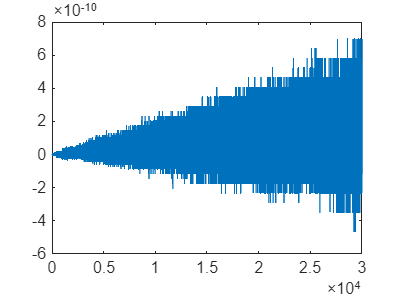

figure; plot(t, yJ2B - y_t);

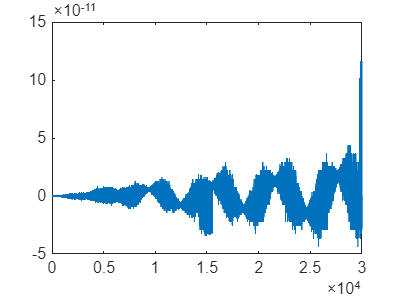

figure; plot(t, zJ2B - z_t);

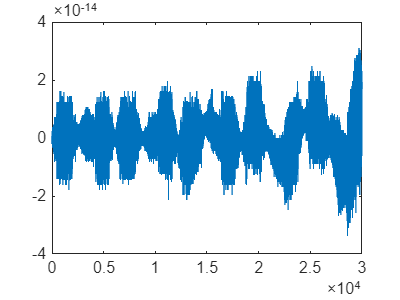




xdotJ2B = ((480.*a.*n.^2.*sin(n.*t) - 1920.*a.*e.^2.*n.^2.*sin(n.*t) + 2880.*a.*e.^4.*n.^2.*sin(n.*t) - 1920.*a.*e.^6.*n.^2.*sin(n.*t) + 480.*a.*e.^8.*n.^2.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*x0 + ((160.*a.*n.*cos(n.*t) - 640.*a.*e.^2.*n.*cos(n.*t) + 960.*a.*e.^4.*n.*cos(n.*t) - 640.*a.*e.^6.*n.*cos(n.*t) + 160.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*dx0 + ((320.*a.*n.*sin(n.*t) - 1280.*a.*e.^2.*n.*sin(n.*t) + 1920.*a.*e.^4.*n.*sin(n.*t) - 1280.*a.*e.^6.*n.*sin(n.*t) + 320.*a.*e.^8.*n.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*dy0 + (-(60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^3.*cos(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^3.*cos(2.*omega + n.*t) + 120.*R.^2.*e.*n.^3.*cos(theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^3.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t))./(a.*n.*(- 1 + e.^2).^4.*160)).*t.*J2 + ((15.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 35.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 15.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 35.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 20.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 60.*R.^2.*n.^2.*sin(n.*t) - 30.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 70.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 40.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 90.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 90.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 240.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 105.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 10.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 21.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 75.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 4.*n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) + 330.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 210.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 30.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 30.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 70.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 210.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 20.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 150.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 128.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 4.*n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) - 660.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 420.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 60.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 140.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 80.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 35.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 35.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) - 40.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) - 40.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 2.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 75.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 90.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) + 70.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) + 80.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 2.*n.*t) - 150.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./(a.*n.*(- 1 + e.^2).^4.*160) - (60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 180.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 120.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 960.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 480.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(a.*n.*(- 1 + e.^2).^4.*160)).*J2;
ydotJ2B = (-(480.*a.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 2880.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 1920.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 480.*a.*e.^8.*n.*sin((n.*t)./2).^2)./(a.*(- 1 + e.^2).^4.*40)).*x0 + (-(80.*sin(n.*t).*a - 320.*sin(n.*t).*a.*e.^2 + 480.*sin(n.*t).*a.*e.^4 - 320.*sin(n.*t).*a.*e.^6 + 80.*sin(n.*t).*a.*e.^8)./(a.*(- 1 + e.^2).^4.*40)).*dx0 + ((40.*a - 160.*a.*e.^2 + 240.*a.*e.^4 - 160.*a.*e.^6 + 40.*a.*e.^8 - 320.*a.*sin((n.*t)./2).^2 + 1280.*a.*e.^2.*sin((n.*t)./2).^2 - 1920.*a.*e.^4.*sin((n.*t)./2).^2 + 1280.*a.*e.^6.*sin((n.*t)./2).^2 - 320.*a.*e.^8.*sin((n.*t)./2).^2)./(a.*(- 1 + e.^2).^4.*40)).*dy0 + ((30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) + 90.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) + 60.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) - 360.*R.^2.*e.^2.*n.^2.*sin(2.*omega) - 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega) + 180.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega))./(a.*(- 1 + e.^2).^4.*40)).*t.*J2 + ((5.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 35.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 15.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 90.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 5.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 15.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 60.*R.^2.*n.*sin((n.*t)./2).^2 - 90.*R.^2.*n.*sin(omega + theta_0).^2 - 180.*R.^2.*n.*sin(INC).^2 - 10.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 70.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 30.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 45.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 35.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 30.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 420.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 + 420.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 120.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 21.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 180.*R.^2.*e.*n.*sin(omega + theta_0./2).^2 - 60.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 480.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 + 30.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 30.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 - 20.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 20.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + n.*t).^2 + 140.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 + 60.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 70.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 30.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 90.*R.^2.*e.*n.*sin(INC + omega + theta_0./2).^2 + 30.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 240.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 + 105.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + 2.*n.*t).^2 + 21.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 10.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 - 15.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 60.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 210.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 - 210.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 - 90.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 10.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 10.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + n.*t).^2 - 70.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 - 30.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 35.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 15.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 105.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 120.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 15.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + 2.*n.*t).^2 - 42.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 20.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 + 30.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2)./(a.*(- 1 + e.^2).^4.*40)).*J2;
zdotJ2B = (-(8.*a.*n.^2.*sin(n.*t) - 32.*a.*e.^2.*n.^2.*sin(n.*t) + 48.*a.*e.^4.*n.^2.*sin(n.*t) - 32.*a.*e.^6.*n.^2.*sin(n.*t) + 8.*a.*e.^8.*n.^2.*sin(n.*t))./(a.*n.*(- 1 + e.^2).^4.*8)).*z0 + ((8.*a.*n.*cos(n.*t) - 32.*a.*e.^2.*n.*cos(n.*t) + 48.*a.*e.^4.*n.*cos(n.*t) - 32.*a.*e.^6.*n.*cos(n.*t) + 8.*a.*e.^8.*n.*cos(n.*t))./(a.*n.*(- 1 + e.^2).^4.*8)).*dz0 + (-(6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 12.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0))./(a.*n.*(- 1 + e.^2).^4.*8)).*t.*J2 + ((6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega))./(a.*n.*(- 1 + e.^2).^4.*8) - (6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 6.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) + 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 18.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 18.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 12.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 24.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 5.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 16.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 9.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega))./(a.*n.*(- 1 + e.^2).^4.*8)).*J2;

x_dot = dx0.*cos(2*eta) ...
        - 2.*dy0.*cos(eta) ...
        + 6.*n.*x0.*cos((n.*t)./2).*sin((n.*t)./2) ...
        - n*J2*R^2/(40*a*(e^2 - 1)^4)*( ...
        + e^2*sin(INC)^2*( ...
            - 240*sin(2*beta1) ...
            + 75*sin(2*beta6) ...
            + 105*sin(2*beta8) ...
            - 10*sin(2*beta16) ...
            - 75*sin(2*beta18) ...
            + 64*sin(2*beta19) ...
            + 21*sin(2*beta20) ...
            + 330*sin(2*o1) ...
            + 210*sin(2*o3) ...
            - 120*( 4.*sin(2.*omega) - cos(beta10).*sin(theta_0) ) ...
            - 240*eta.*sin(beta10).*sin(theta_0) ...
        ) ...
        + 5*e*( ...
            sin(INC).^2.*( ...
                6*sin(beta10) ...
                + 8*sin(beta11) ...
                - 14*sin(beta12) ...
                - 8*sin(beta13) ...
                + 15*sin(beta14) ...
                - 7*sin(beta15) ...
                + 36*cos(2*eta).*sin(theta_0) ...
            ) ...
            - 24*cos(2*eta).*sin(theta_0) ...
            + 6*sin(tau1).*kappa_i ...
            + 12*eta.*cos(tau1).*kappa_i ...
        ) ...
        + 5*sin(INC).^2.*( ...
            3*sin(2*beta1) ...
            + 4*sin(2*beta5) ...
            - 7*sin(2*beta8) ...
        ) ...
        + 15*sin(2*eta).*kappa_i);
y_dot = -12.*n.*sin(eta).^2.*x0 ...
        - 2.*sin(2*eta).*dx0 ...
        + (1 - 8.*eta.^2).*dy0 ...
        + (n*R^2*J2) / (20*a*(e^2 - 1)^4).*( ...
            + e^2*sin(INC).^2.*( ...    
                + 120*cos(2*beta1) ...
                + 15*cos(2*beta6) ...
                + 105*cos(2*beta8) ...   
                + 10*cos(2*beta16) ...
                - 15*cos(2*beta18) ...
                + 14*cos(2*beta19) ...
                + 21*cos(2*beta20) ...
                - 210*cos(2*o1) ...
                + 210*cos(2*o3) ...
                + 480*sin(alpha1).^2 ...
                - 30*cos(2*alpha4) ... 
                - 240 ...                             
                + 120*eta.*( ...
                    + sin(2*beta1) ...
                    - sin(2*o1) ...
                    - 6*sin(2*omega) ...
                ) ...
            ) ...
            + 5*e*( ...
                + sin(INC).^2.*( ...
                    - 6*cos(beta10) ...
                    + 2*cos(beta11) ...
                    - 14*cos(beta12) ...
                    - 2*cos(beta13) ...
                    - 7*cos(beta15) ...
                    + 3*cos(beta14) ...
                    + 18*cos(alpha2) ...
                    + 6*cos(alpha3) ...
                ) ...
                - 6*kappa_i.*( ...
                    + sin(2*eta)*sin(theta_0) ...
                    - 2*eta.*sin(tau1) ...
                ) ...
            ) ...
            + 10*( ...
                + 4*sin(eta).^2.*( ...
                    3 ...
                    - sin(INC).^2*(2 + 5.*sin(alpha1).^2) ...
                ) ...
                + sin(INC).^2.*( ...
                    + sin(alpha1).^2 ...
                    - sin(beta5).^2 ...
                    - 2*sin(2*eta).*sin(2*alpha1) ...
                ) ...
            ) ...
        );
z_dot = dz0.*cos(n.*t) ...
        - n.*z0.*sin(n.*t) ...
        - n*J2.*R.^2.*sin(2.*INC)./(8.*a.*(e.^2 - 1).^4).*( ...
        - e.^2.*( ...
            - 24*cos(beta5) ...
            + 16*cos(beta7) ...
            + 8*cos(beta9) ...
            + 6*cos(beta22) ...
            - 16*cos(beta23) ...
            + 9*cos(beta24) ...
            + cos(beta25) ...
            + 6*cos(beta26) ...
            - 6*cos(beta27) ...
            + 24*eta.*sin(beta27) ...
        ) ...
        + 3.*e.*( ...
            + 5*cos(beta17) ...
            - 8*cos(beta19) ...
            + cos(beta21) ...
            - cos(o2) ...
            + 3*cos(o4) ...
            + 2*( cos(beta17) - cos(o2) ) ...
            - 4*eta.*( sin(beta17) - sin(o2) ) ...
            ) ...
        - 3*( cos(beta5) - cos(beta9) - 4*eta.*sin(beta5) ) ...
        );

figure; plot(t, xdotJ2B - x_dot);

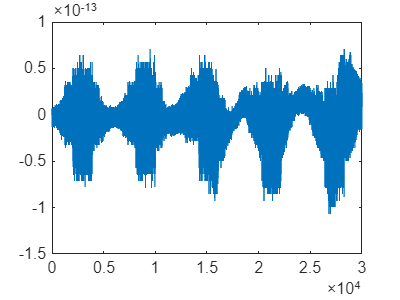

figure; plot(t, ydotJ2B - y_dot);

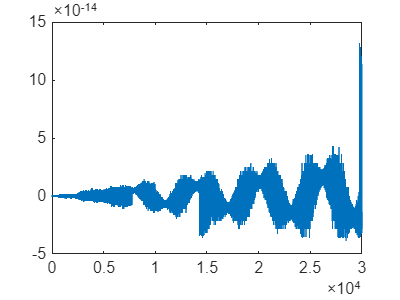

figure; plot(t, zdotJ2B - z_dot);